# Symbolic Matrix Computation

This example shows how to perform simple matrix computations using Symbolic Math Toolbox™.

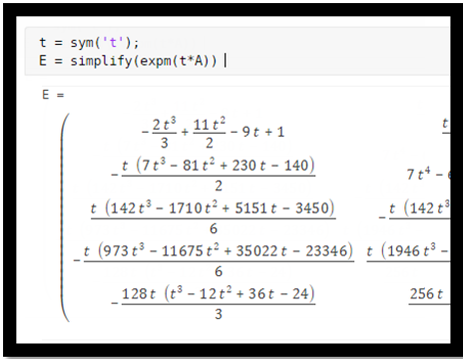

Generate a possibly familiar test matrix, the 5-by-5 Hilbert matrix.

H = sym(hilb(5)) 

The determinant is very small.

d = det(H) 

The elements of the inverse are integers.

X = inv(H) 

Verify that the inverse is correct.

I = X*H

Find the characteristic polynomial.

syms x; p = charpoly(H,x) 

Try to factor the characteristic polynomial.

factor(p) 

The result indicates that the characteristic polynomial cannot be factored over the rational numbers.

Compute the 50 digit numerical approximations to the eigenvalues.

digits(50) 
e = eig(vpa(H)) 

Create a generalized Hilbert matrix involving a free variable, $t$.

t = sym('t'); 
[I,J] = meshgrid(1:5); 
H = 1./(I+J-t)

Substituting $t = 1
$ retrieves the original Hilbert matrix.

subs(H,t,1) 

The reciprocal of the determinant is a polynomial in $t$.

d = 1/det(H) 
d = expand(d)

The elements of the inverse are also polynomials in $t$.

X = inv(H) 

Substituting $t = 1 $ generates the Hilbert inverse.

X = subs(X,t,'1') 
X = double(X) 

Investigate a different example.

A = sym(gallery(5)) 

This matrix is "nilpotent". It's fifth power is the zero matrix.

A^5 

Because this matrix is nilpotent, its characteristic polynomial is very simple.

p = charpoly(A,'lambda') 

You should now be able to compute the matrix eigenvalues in your head. They are the zeros of the equation lambda^5 = 0.

Symbolic computation can find the eigenvalues exactly.

lambda = eig(A) 

Numeric computation involves roundoff error and finds the zeros of an equation that is something like lambda^5 = eps*norm(A) So the computed eigenvalues are roughly lambda = (eps*norm(A))^(1/5) Here are the eigenvalues, computed by the Symbolic Toolbox using 16 digit floating point arithmetic. It is not obvious that they should all be zero.

digits(16) 
lambda = eig(vpa(A)) 

This matrix is also "defective". It is not similar to a diagonal matrix. Its Jordan Canonical Form is not diagonal.

J = jordan(A) 

The matrix exponential, expm(t*A), is usually expressed in terms of scalar exponentials involving the eigenvalues, exp(lambda(i)*t). But for this matrix, the elements of expm(t*A) are all polynomials in t.

t = sym('t'); 
E = simplify(expm(t*A)) 

By the way, the function "exp" computes element-by-element exponentials.

X = exp(t*A) 

*Copyright 2016 The MathWorks, Inc.*